ks = 0.5

ks = 0.5000

m = 1.0

m = 1

q1 = 2.0 

q1 = 2

q2 = 2.0 

q2 = 2

kc = 5.0 

kc = 5

l0 = 10.0 

l0 = 10

h = 0.01

h = 0.0100

y = 10

y = 10

%%
syms y(t)
[V] = odeToVectorField(diff(y, 2) ==  -ks/m* (y-l0)+kc*q1*q2/y^2)

$$V = \left(\begin{array}{c} Y_{2}\\ \frac{20}{{Y_{1}}^{2}}-\frac{Y_{1}}{2}+5 \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);1.0./Y(1).^2.*2.0e+1-Y(1)./2.0+5.0]



sol = ode45(M,[0 20],[10 0])

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.0010 0.0060 0.0311 0.1567 0.7847 1.7905 2.9257 4.1920 5.3237 6.4554 7.6146 9.0407 10.2707 11.3903 12.6269 13.7828 14.9387 16.0886 17.4632 18.7518 19.8673 20]
          y: [2×23 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


x = linspace(0,20,50)

x =          0    0.4082    0.8163    1.2245    1.6327    2.0408    2.4490    2.8571    3.2653    3.6735    4.0816    4.4898    4.8980    5.3061    5.7143    6.1224    6.5306    6.9388    7.3469    7.7551    8.1633    8.5714    8.9796    9.3878    9.7959   10.2041   10.6122   11.0204   11.4286   11.8367   12.2449   12.6531   13.0612   13.4694   13.8776   14.2857   14.6939   15.1020   15.5102   15.9184   16.3265   16.7347   17.1429   17.5510   17.9592   18.3673   18.7755   19.1837   19.5918   20.0000


y = deval(sol,x,1)

y =    10.0000   10.0165   10.0647   10.1401   10.2361   10.3442   10.4547   10.5579   10.6447   10.7074   10.7402   10.7406   10.7085   10.6465   10.5604   10.4575   10.3470   10.2387   10.1423   10.0663   10.0171    9.9998   10.0158   10.0632   10.1380   10.2337   10.3416   10.4522   10.5556   10.6429   10.7061   10.7397   10.7410   10.7096   10.6483   10.5626   10.4601   10.3497   10.2412   10.1445   10.0678   10.0180   10.0000   10.0151   10.0617   10.1359   10.2313   10.3390   10.4495   10.5533


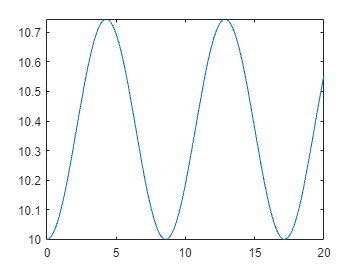

fplot(@(x)deval(sol,x,1), [0, 20])

syms g(x)

g(x) = m*(x-y)^2+h^2*(0.5*ks*(x-l0)^2+kc*q1*q2/x)

Error using  ^ 
Matrix must be square.

%g(x) = sin(x^2)
dg=diff(g,x)
eqn  = dg == 0
S = solve(eqn,x)